# Modelos cinemáticos de un robot serial 4R en el espacio

## Resumen

Este archivo incluye el planteamiento del modelo cinemático directo de la postura, el modelo cinemático directo de las velocidades, y el modelo cinemático inverso de la postura, junto con su solución.

## Bloque de funciones

Función general para una transformación homogénea entre dos sistemas de referencia, considerando traslaciones y rotaciones en 3D.

% Transformación homogenea
syms T_i_j(x_i_j, y_i_j, z_i_j, gamma_i_j, beta_i_j, alpha_i_j)
T_i_j(x_i_j, y_i_j, z_i_j, gamma_i_j, beta_i_j, alpha_i_j) = [cos(alpha_i_j)*cos(beta_i_j) cos(alpha_i_j)*sin(beta_i_j)*sin(gamma_i_j)-sin(alpha_i_j)*cos(gamma_i_j) sin(alpha_i_j)*sin(gamma_i_j)+cos(alpha_i_j)*sin(beta_i_j)*cos(gamma_i_j) x_i_j; sin(alpha_i_j)*cos(beta_i_j) cos(alpha_i_j)*cos(gamma_i_j)+sin(alpha_i_j)*sin(beta_i_j)*sin(gamma_i_j) sin(alpha_i_j)*sin(beta_i_j)*cos(gamma_i_j)-cos(alpha_i_j)*sin(gamma_i_j) y_i_j; -sin(beta_i_j) cos(beta_i_j)*sin(gamma_i_j) cos(beta_i_j)*cos(gamma_i_j) z_i_j; 0 0 0 1]

$$T\_i\_j(x\_i\_j, y\_i\_j, z\_i\_j, gamma\_i\_j, beta\_i\_j, alpha\_i\_j) = \left(\begin{array}{cccc} \cos\left(\alpha_{i,j}\right)\,\cos\left(\beta_{i,j}\right) & \cos\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)-\cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \sin\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right)+\cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)\,\sin\left(\beta_{i,j}\right) & x_{i,j}\\ \cos\left(\beta_{i,j}\right)\,\sin\left(\alpha_{i,j}\right) & \cos\left(\alpha_{i,j}\right)\,\cos\left(\gamma_{i,j}\right)+\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\gamma_{i,j}\right)\,\sin\left(\alpha_{i,j}\right)\,\sin\left(\beta_{i,j}\right)-\cos\left(\alpha_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & y_{i,j}\\ -\sin\left(\beta_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\sin\left(\gamma_{i,j}\right) & \cos\left(\beta_{i,j}\right)\,\cos\left(\gamma_{i,j}\right) & z_{i,j}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

## Sistemas de referencia

El robot serial 4R tiene cinco eslabones en serie conectados por 4 juntas rotacionales.  El modelo desarrollado es una simplificación del Scorbot, omitiendo la orientación del efector final dada por el "roll" de la muñeca, tal como se muestra en la siguiente figura.

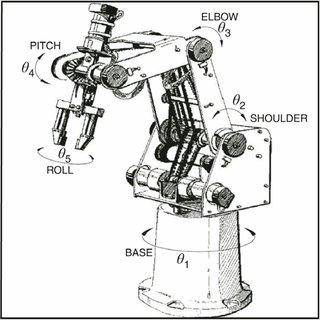

Para modelar el robot, se definen las relaciones de posición y orientación entre eslabones mediante sistemas de referencia. La cadena cinemática del robot se construye a partir de transformaciones homogenes, las cuales describen las traslaciones y rotaciones que relacionan los sistemas. Las siguientes figuras muestran los sistemas de referencia definidos.

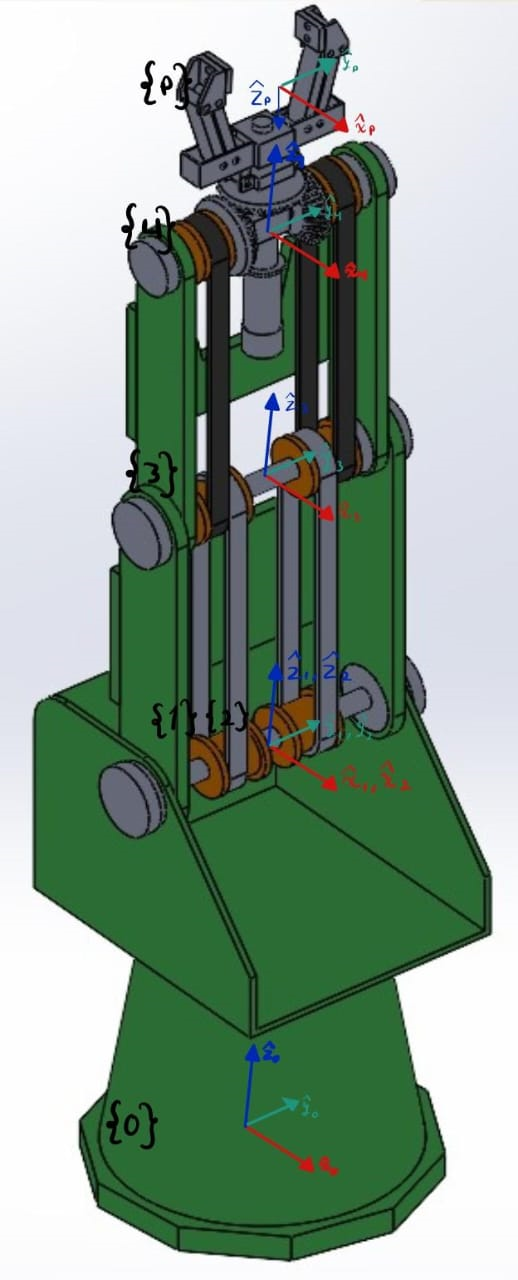

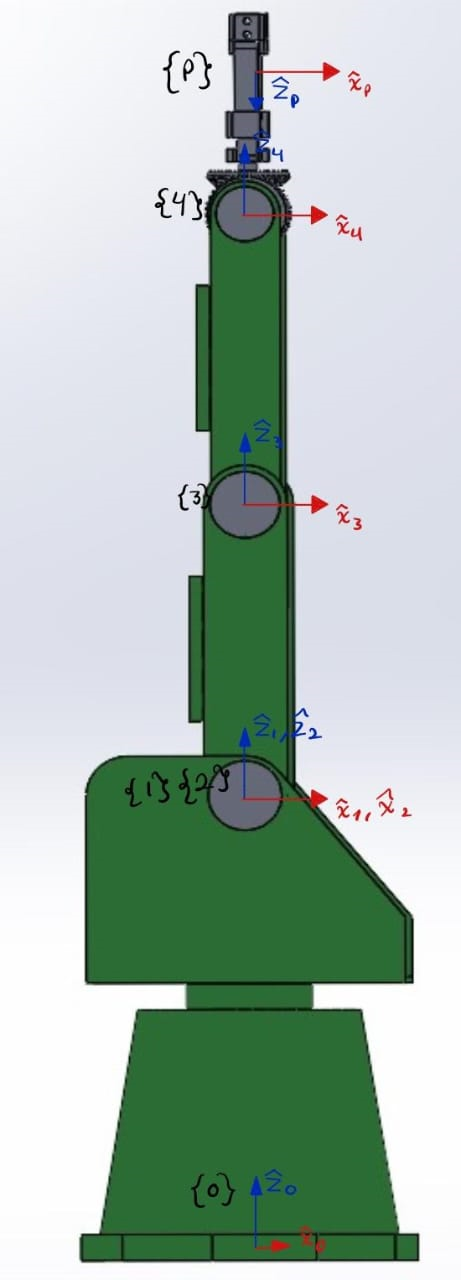

## Modelo cinemático directo de la postura

El modelo cinemático directo de la postura se determina mediante la transformación homogénea que relaciona el sistema inercial {0} con el sistema {p} asociado al efector final. Para ello, se establecen las transformaciones homogéneas que describen la relación entre los sistemas intermedios.

#### Sistema {1} visto desde el sistema {0}

La transformación incluye una traslación a lo largo del eje ${\hat{z} }_0$, cuya magnitud${}^0z_1$representa la altura desde la base hasta la junta del hombro, y una rotación alrededor del eje ${\hat{z} }_1$ con un ángulo${}^0{\theta }_1$que describe el movimiento de la cintura del robot.

syms T_0_1 z_0_1 theta_0_1 
T_0_1 = T_i_j(0, 0, z_0_1, 0, 0, theta_0_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & 0 & 0\\ \sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & 0 & 0\\ 0 & 0 & 1 & z_{0,1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Sistema {2} visto desde el sistema {1}

La transformación no incluye traslaciones, ya que los sistemas comparten el mismo punto de origen; sin embargo, incluye una rotación alrededor del eje ${\hat{y} }_2$ con un ángulo${}^1{\theta }_2$que describe el movimiento del hombro del robot.

syms T_1_2 theta_1_2
T_1_2 = T_i_j(0, 0, 0, 0, theta_1_2, 0)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1,2}\right) & 0 & \sin\left(\theta_{1,2}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{1,2}\right) & 0 & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Sistema {3} visto desde el sistema {2}

La transformación incluye una traslación a lo largo del eje ${\hat{z} }_2$, cuya magnitud${}^2z_3$representa la longitud del brazo del robot, y una rotación alrededor del eje ${\hat{y} }_3$ con un ángulo${}^2{\theta }_3$que describe el movimiento del codo del robot.

syms T_2_3 z_2_3 theta_2_3
T_2_3 = T_i_j(0, 0, z_2_3, 0, theta_2_3, 0)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{2,3}\right) & 0 & \sin\left(\theta_{2,3}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{2,3}\right) & 0 & \cos\left(\theta_{2,3}\right) & z_{2,3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Sistema {4} visto desde el sistema {3}

La transformación incluye una traslación a lo largo del eje ${\hat{z} }_3$, cuya magnitud${}^3z_4$representa la longitud del antebrazo del robot, y una rotación alrededor del eje ${\hat{y} }_4$ con un ángulo${}^3{\theta }_4$que describe el movimiento de la muñeca del robot.

syms T_3_4 z_3_4 theta_3_4
T_3_4 = T_i_j(0, 0, z_3_4, 0, theta_3_4, 0)

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right) & 0\\ 0 & 1 & 0 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left(\theta_{3,4}\right) & z_{3,4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Sistema {p} visto desde el sistema {4}

La transformación solo incluye una traslación a lo largo del eje ${\hat{z} }_4$, cuya magnitud${}^4z_p$representa la distancia desde la muñeca hasta el punto en el gripper donde el robot puede manipular objetos.

syms T_4_p z_4_p
T_4_p = T_i_j(0, 0, z_4_p, 0, 0, 0)

$$T\_4\_p = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & z_{4,p}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Sistema {p} visto desde el sistema {0}

La transformación homogenea que relaciona el sistema inercial con el sistema del efector final se determina mediante la composición de las transformaciones homogeneas intermedias.


$${}^0T_p={}^0T_1{}^1T_2{}^2T_3{}^3T_4{}^4T_p$$


syms T_0_P
T_0_P = simplify(T_0_1*T_1_2*T_2_3*T_3_4*T_4_p)

$$T\_0\_P = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\cos\left(\theta_{0,1}\right) & -\sin\left(\theta_{0,1}\right) & \sigma_{3}\,\cos\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right)\,\sigma_{2}\\ \sigma_{1}\,\sin\left(\theta_{0,1}\right) & \cos\left(\theta_{0,1}\right) & \sigma_{3}\,\sin\left(\theta_{0,1}\right) & \sin\left(\theta_{0,1}\right)\,\sigma_{2}\\ -\sigma_{3} & 0 & \sigma_{1} & z_{0,1}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,p}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{2}=z_{4,p}\,\sigma_{3}+z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right)\\ \sigma_{3}=\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right) \end{array}$$

#### Vector de postura del efector final

El vector de postura se define a partir de los vectores de posición y orientación del efector final.


$${}^0{\xi }_p={}^0{\xi }_p\left(q\right)$$


syms xi_0_P
xi_0_P = [T_0_P(1,4); T_0_P(2,4); T_0_P(3,4); atan2(T_0_P(3,2), T_0_P(3,3)); atan2(-T_0_P(3,1), sqrt(T_0_P(3,2)^2 + T_0_P(3,3)^2)); atan2(T_0_P(2,1), T_0_P(1,1))]

$$xi\_0\_P = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta_{0,1}\right)\,\sigma_{2}\\ \sin\left(\theta_{0,1}\right)\,\sigma_{2}\\ z_{0,1}+z_{3,4}\,\cos\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\cos\left(\theta_{1,2}\right)+z_{4,p}\,\sigma_{1}\\ \frac{\pi \,\mathrm{sign}\left(\sigma_{1}\right)\,\left(\mathrm{sign}\left(\sigma_{1}\right)-1\right)}{2}\\ \text{atan2}\left(\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right),\sqrt{{\sigma_{1}}^{2}}\right)\\ \text{atan2}\left(\sigma_{1}\,\sin\left(\theta_{0,1}\right),\sigma_{1}\,\cos\left(\theta_{0,1}\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)\\ \sigma_{2}=z_{4,p}\,\sin\left(\theta_{1,2}+\theta_{2,3}+\theta_{3,4}\right)+z_{3,4}\,\sin\left(\theta_{1,2}+\theta_{2,3}\right)+z_{2,3}\,\sin\left(\theta_{1,2}\right) \end{array}$$

## Modelo cinemático directo de las velocidades

El modelo cinemático directo de las velocidades se obtiene mediante la derivada total del modelo cinemático directo de la postura.


$${}^0{\dot{\xi} }_p=J_{\theta } \left(q\right)\dot{q}$$


#### Matriz Jacobiana

syms J_theta
J_theta = jacobian(xi_0_P, [theta_0_1, theta_1_2, theta_2_3, theta_3_4])

#### Vector de velocidades de las juntas

syms theta_dot theta_dot_0_1 theta_dot_1_2 theta_dot_2_3 theta_dot_3_4
theta_dot = [theta_dot_0_1; theta_dot_1_2; theta_dot_2_3; theta_dot_3_4]

$$theta\_dot = \left(\begin{array}{c} {\dot{\theta }}_{0,1}\\ {\dot{\theta }}_{1,2}\\ {\dot{\theta }}_{2,3}\\ {\dot{\theta }}_{3,4} \end{array}\right)$$

#### Vector de velocidades del efector final

syms xi_dot_0_p
xi_dot_0_P = J_theta*theta_dot

## Modelo cinemático inverso de la postura

El modelo cinemático inverso de la postura define geométricamente los ángulos de las juntas del robot: cintura, hombro, codo y muñeca, a partir del vector de postura deseada del efector final. El planteamiento se desarrolla con base en el diagrama mostrado en la siguiente figura.

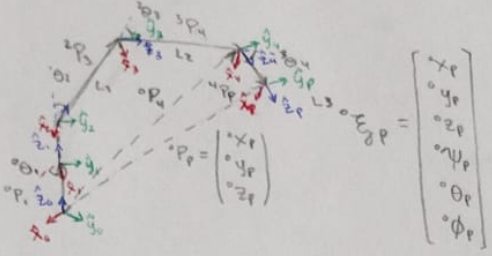

#### Vector de postura deseada del efector final

En el modelo cinemático inverso de la postura se definen la posición y orientación del efector final en el vector de postura.

syms x_0_p y_0_p z_0_p psi_0_p theta_0_p phi_0_p
xi_0_P = [x_0_p; y_0_p; z_0_p; psi_0_p; theta_0_p; phi_0_p]

$$xi\_0\_P = \left(\begin{array}{c} x_{0,p}\\ y_{0,p}\\ z_{0,p}\\ \psi_{0,p}\\ \theta_{0,p}\\ \varphi_{0,p} \end{array}\right)$$

#### Matriz de rotación

Del vector de postura deseada del efector final se obtiene la matriz de rotación ${}^0R_p$.

syms R_0_p(psi_0_p, theta_0_p, phi_0_p)
R_0_p(psi_0_p, theta_0_p, phi_0_p) = [cos(phi_0_p)*cos(theta_0_p) cos(phi_0_p)*sin(theta_0_p)*sin(psi_0_p)-sin(phi_0_p)*cos(psi_0_p) sin(phi_0_p)*sin(psi_0_p)+cos(phi_0_p)*sin(theta_0_p)*cos(psi_0_p); sin(phi_0_p)*cos(theta_0_p) cos(phi_0_p)*cos(psi_0_p)+sin(phi_0_p)*sin(theta_0_p)*sin(psi_0_p) sin(phi_0_p)*sin(theta_0_p)*cos(psi_0_p)-cos(phi_0_p)*sin(psi_0_p); -sin(theta_0_p) cos(theta_0_p)*sin(psi_0_p) cos(theta_0_p)*cos(psi_0_p)]

$$R\_0\_p(psi\_0\_p, theta\_0\_p, phi\_0\_p) = \left(\begin{array}{ccc} \cos\left(\varphi_{0,p}\right)\,\cos\left(\theta_{0,p}\right) & \cos\left(\varphi_{0,p}\right)\,\sin\left(\psi_{0,p}\right)\,\sin\left(\theta_{0,p}\right)-\cos\left(\psi_{0,p}\right)\,\sin\left(\varphi_{0,p}\right) & \sin\left(\varphi_{0,p}\right)\,\sin\left(\psi_{0,p}\right)+\cos\left(\varphi_{0,p}\right)\,\cos\left(\psi_{0,p}\right)\,\sin\left(\theta_{0,p}\right)\\ \cos\left(\theta_{0,p}\right)\,\sin\left(\varphi_{0,p}\right) & \cos\left(\varphi_{0,p}\right)\,\cos\left(\psi_{0,p}\right)+\sin\left(\varphi_{0,p}\right)\,\sin\left(\psi_{0,p}\right)\,\sin\left(\theta_{0,p}\right) & \cos\left(\psi_{0,p}\right)\,\sin\left(\varphi_{0,p}\right)\,\sin\left(\theta_{0,p}\right)-\cos\left(\varphi_{0,p}\right)\,\sin\left(\psi_{0,p}\right)\\ -\sin\left(\theta_{0,p}\right) & \cos\left(\theta_{0,p}\right)\,\sin\left(\psi_{0,p}\right) & \cos\left(\psi_{0,p}\right)\,\cos\left(\theta_{0,p}\right) \end{array}\right)$$

#### Desacoplamiento

El desacoplamiento de la cinemática facilita el desarrollo del modelo y su solución. Para ello, se establece la relación entre los vectores${}^0P_4$, ${}^0P_p$ y ${}^4P_p$. Dado que el vector ${}^0{\hat{z} }_4$ es colineal al vector ${}^0{\hat{z} }_p$, y que éste último es la tercera columna de la matriz de rotación${}^0R_p$.

syms P_0_p P_4_p L_3 z_0_4
P_4_p = P_0_p - L_3*z_0_4

$$P\_4\_p = P_{0,p}-L_{3}\,z_{0,4}$$

#### Ángulo asociado al sistema {1} (cintura)

El ángulo asociado a la cintura únicamente depende de la proyección del sistema {p} sobre el plano $\textrm{XY}$ del sistema inercial {0}. Por lo tanto, el ángulo ${}^0{\theta }_1$ se obtiene con la función $\textrm{atan2}$ de los elementos${}^0x_p$ y ${}^0y_p$ del vector de postura deseada del efector final.

theta_0_1 = atan2(y_0_p,x_0_p)

$$theta\_0\_1 = \text{atan2}\left(y_{0,p},x_{0,p}\right)$$

#### Relación entre ángulos

Los ángulos ${}^1{\theta }_2$, ${}^2{\theta }_3$ y ${}^3{\theta }_4$ se obtienen a partir de las relaciones geométricas mostradas en la siguiente figura.

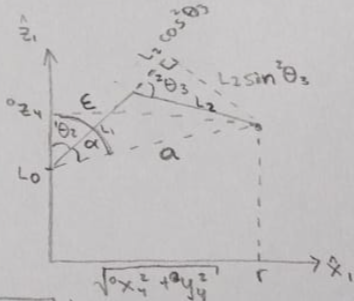

#### Ángulo asociado al sistema {2} (hombro)

El ángulo asociado al hombro se establece con la relación de los ángulos $\varepsilon$ y $\alpha$. Ambos ángulos se describen desde el vector $\bar{a}$, cuya magnitud $a$ se utiliza para expresarlos.

syms a x_0_4 y_0_4 L_0
a = sqrt((x_0_4)^2+(y_0_4)^2+(z_0_4-L_0)^2)

$$a = \sqrt{{x_{0,4}}^{2}+{y_{0,4}}^{2}+{\left(L_{0}-z_{0,4}\right)}^{2}}$$

Esta magnitud también puede expresarse a partir del triángulo rectángulo formado por el vector $\bar{a}$, el vector $L_1$, y las proyecciones de $L_2$ respecto al ángulo${}^2{\theta }_3$.

syms L_1 L_2
a = sqrt((L_1+L_2*cos(theta_2_3))^2+(L_2*sin(theta_2_3))^2)

$$a = \sqrt{{L_{2}}^{2}\,{\sin\left(\theta_{2,3}\right)}^{2}+{\left(L_{1}+L_{2}\,\cos\left(\theta_{2,3}\right)\right)}^{2}}$$

De esta forma, el ángulo $\varepsilon$ formado entre el vector unitario ${\hat{z} }_1$ y el vector $\bar{a}$ se define:

syms epsilon 
epsilon = atan2(sqrt((x_0_4)^2+(y_0_4)^2),z_0_4-L_0)

$$epsilon = \text{atan2}\left(\sqrt{{x_{0,4}}^{2}+{y_{0,4}}^{2}},z_{0,4}-L_{0}\right)$$

De esta forma, el ángulo $\alpha$ formado entre el vector $L_1$ y el vector $\bar{a}$ se define:

syms alpha 
alpha = atan2(L_2*sin(theta_2_3),L_1+L_2*cos(theta_2_3))

$$alpha = \text{atan2}\left(L_{2}\,\sin\left(\theta_{2,3}\right),L_{1}+L_{2}\,\cos\left(\theta_{2,3}\right)\right)$$

Por lo tanto: 

theta_1_2 = epsilon - alpha

$$theta\_1\_2 = -\text{atan2}\left(L_{2}\,\sin\left(\theta_{2,3}\right),L_{1}+L_{2}\,\cos\left(\theta_{2,3}\right)\right)+\text{atan2}\left(\sqrt{{x_{0,4}}^{2}+{y_{0,4}}^{2}},z_{0,4}-L_{0}\right)$$

#### Ángulo asociado al sistema {3} (codo)

El angulo asociado al codo se obtiene de la ley de cosenos planteada a partir del vector $\bar{a}$.

theta_2_3 = acos(((x_0_4)^2+(y_0_4)^2+(L_0-z_0_4)^2)/(2*L_1*L_2))

$$theta\_2\_3 = \mathrm{acos}\left(\frac{{x_{0,4}}^{2}+{y_{0,4}}^{2}+{\left(L_{0}-z_{0,4}\right)}^{2}}{2\,L_{1}\,L_{2}}\right)$$

#### Ángulo asociado al sistema {4} (muñeca)

El ángulo asociado a la muñeca se obtiene descomponiendo la matriz de rotación${}^0R_p$. La rotación total desde el sistema inercial incluye la rotación $R_z$ con el ángulo${}^0{\theta }_1$, la rotación $R_y$ con la suma de los ángulos${}^1{\theta }_2$y${}^2{\theta }_3$, y la rotación${}^3R_p$ del efector final. Al despejar esta última, se obtiene ${\left(R_z R_y \right)}^T {}^0R_p$:

R_3_p = [cos(theta_3_4) 0 sin(theta_3_4); 0 1 0; -sin(theta_3_4) 0 cos(theta_dot_3_4)]

$$R\_3\_p = \left(\begin{array}{ccc} \cos\left(\theta_{3,4}\right) & 0 & \sin\left(\theta_{3,4}\right)\\ 0 & 1 & 0\\ -\sin\left(\theta_{3,4}\right) & 0 & \cos\left({\dot{\theta }}_{3,4}\right) \end{array}\right)$$

De esta forma, el ángulo se obtiene del primer elemento de la matriz de rotación${}^3R_p$:

theta_3_4 = acos(R_3_p(1,1))

$$theta\_3\_4 = \mathrm{acos}\left(\cos\left(\theta_{3,4}\right)\right)$$